# What should the basis functions be for fitting the raw tongue signals?

Some fluorophores are present at different tissue layers.  In the tonuge, the superficial layers (epithelial) contain FAD, NADH, and keratin in certain locations.  These are not going to be impacted by blood absorptions.  The blood is below the epithelial layer.

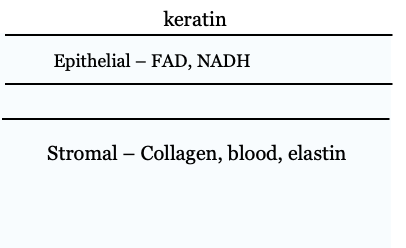

We have data about the excitations of each of these fluorophores in the isetfluorescence repository.  We read them in along with examples of raw data taken from our subjects' tongues and lips.  

We choose which of the published fluorophores to use in the script s_eoBloodFluorophoreBasis.mlx. 

The reason we think blood is necessary is because the raw data - directory spectral photometry measures from the tongue and lip - show some signs of the dips that are well known to be part of the blood absorbance (transmittance) measured in different contexts.

To support the calculations of absorbance and transmittance we created a Matlab class called 'medium', which helps us keep track of the relationship between absorbance, absorptance, transmittance and optical density.

## Programming notes

Repositories: isetcam, isetfluorescence and oe_tongue_lip

3/4 of the blood is oxygenated.  We might add in deoxy_ in the future.

## Initialize

Different analyses are based on different wavebands.

ieInit;
wave = 500:600;
normWave = 520;
yscale = 'linear';

## Read a couple of raw data sets

This is the database of raw measurements.

[T,dataDir] = oeDatabaseCreate;

We illustrate with Z's data because he has little porphyrin. 

These are measurements with different excitation lights at max intensity.  All the subjects show the peak shift from 500 to 515 as the excitation light changes from 405 to 450.

Also, notice the very large dip on the lip around 580, but not on the tongue. 

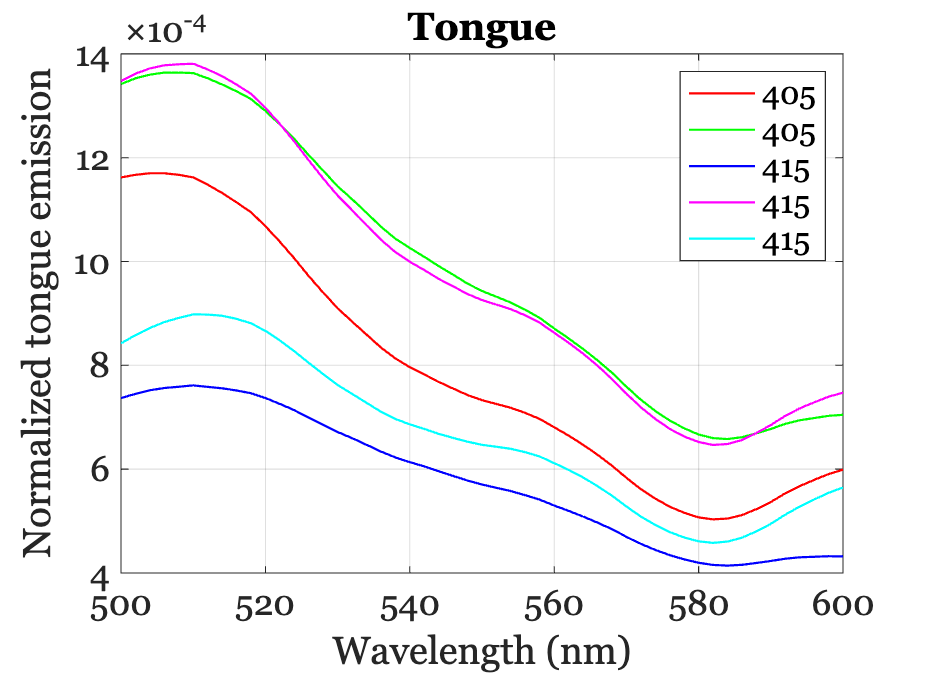

files405 = ieTableGet(T,'subject','B','substrate','tongue','e wave',405,'e level',980);
files415 = ieTableGet(T,'subject','B','substrate','tongue','e wave',415,'e level',910);
tongueFiles = cat(1,files405,files415);

tongueData405 = oeReadFiles(tongueFiles,'normalized wave',normWave,'wave',wave);

files450 = ieTableGet(T,'subject','B','substrate','tongue','e wave',450,'e level',870);
tongueData450 = oeReadFiles(files450,'normalized wave',normWave,'wave',wave);

ieNewGraphWin;
hA = plot(wave,tongueData405,'m-'); hold on;
hB = plot(wave,tongueData450,'b-'); hold on;
grid on;
title('Tongue');
xlabel('Wavelength (nm)'); ylabel('Normalized lip emission'); grid on;

## Select the fluorophores for a basis

Above, we plasted all the fluorophore emissions data in a matrix (fluorophores).  We check how well the full matrix can predict the data samples.  We think it won't without accounting for blood.  

The formula is simple for the full linear calculation


$$d=\textrm{Fw}$$


## Load fluorophore emissions

We have many fluorophore files from the literature. These are analyzed in s_LoadFluorophoreEmissions.  Apart from FAD, all of the fluorophore emission spectra decline in the wave band from 500-600nm.  Here we plot typical examples of each of the different fluorophores emission spectra. They differ between labs, but the slopes here are typical.

We tried this and then moved to using the FADLin

fluorophoreNames = {'CollagenWuQu','KeratinWuQu', 'NADH_webfluor','FADBecker'};

fluorophoreNames = {'CollagenWuQu','KeratinWuQu',...
    'NADH_webfluor','FADLin'};

[fluorophores,wave] = fiLoadBasis(fluorophoreNames,'wave',wave);

ieNewGraphWin;
plot(wave,fluorophores); grid on;
set(gca,'fontsize',16);
xlabel('Wavelength (nm)'); ylabel('Normalized emission')

## Tongue

Least squares

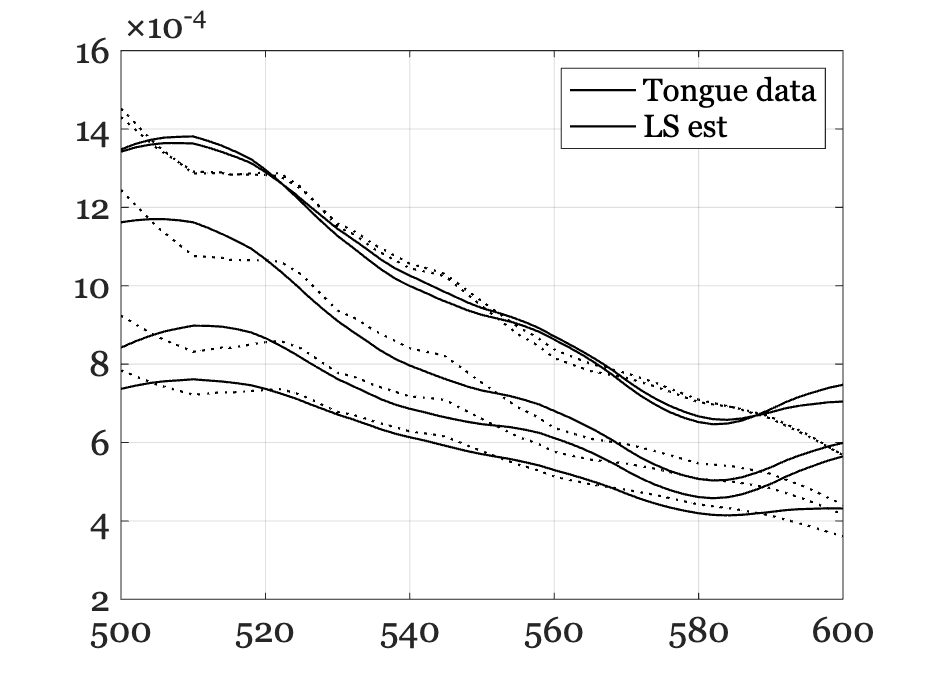

    {'CollagenWuQu' }
    {'KeratinWuQu'  }
    {'NADH_webfluor'}
    {'FADLin'       }

   -0.0068   -0.0058   -0.0031   -0.0077   -0.0053
    0.0019    0.0020    0.0006    0.0027    0.0016
    0.0064    0.0054    0.0034    0.0067    0.0048
    0.0012    0.0012    0.0008    0.0013    0.0010



wgtsLS = pinv(fluorophores)*tongueData;

ieNewGraphWin;
plot(wave,tongueData,'k-',wave,fluorophores*wgtsLS,'k:');
grid on;
legend({'Tongue data','LS est'}); disp(fluorophoreNames'); disp(wgtsLS);

## **Non-negative tongue**

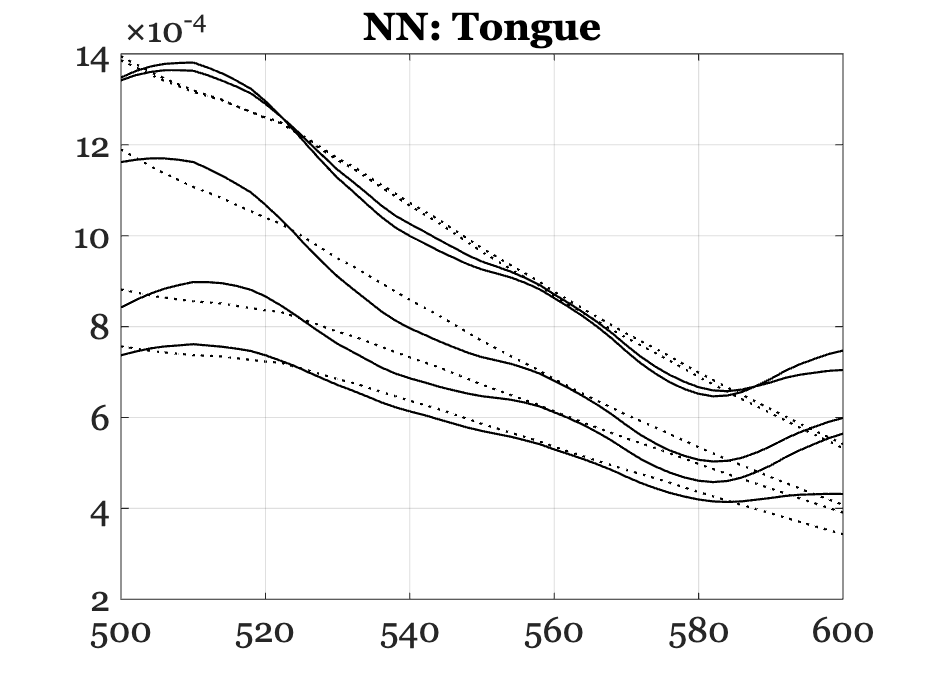

wgtsNN = zeros(size(fluorophores,2),size(tongueData,2));

for dd = 1:size(tongueData,2)
    wgtsNN(:,dd) = lsqnonneg(fluorophores,tongueData(:,dd));
end

ieNewGraphWin;
plot(wave,tongueData,'k-',wave,fluorophores*wgtsNN,'k:');
grid on; title('NN: Tongue')

disp(fluorophoreNames'); disp(wgtsNN);

    {'CollagenWuQu' }
    {'KeratinWuQu'  }
    {'NADH_webfluor'}
    {'FADLin'       }

         0         0         0         0         0
         0         0         0         0         0
    0.0013    0.0015    0.0007    0.0015    0.0009
    0.0004    0.0006    0.0004    0.0006    0.0004



These fits are a little worse, but not terrible.  The main thing to note is the modulation of the data around the predictions.  We think that miss is because we haven't accounted for the blood.

## Read in the oxy data

Let's amend the fluorophore basis by adding in collagen and elastin after some filtering by blood.  Notice that the blood has the two characteristic dips at 540 nm and 580nm.  We see little bumps like that in the raw data (above).

For different purposes we might choose different wavebands.  The raw data are pretty much good from 500-670 or so.  The wavelengths above 600 nm are mainly porphyrin fluorescence (bacteria on the tongue).

We only consider oxygenated blood now because 100% of the blood from the heart lung is oxygenated, and about 50% of the blood in the veins is also oxygenated. 

oxyblood = medium('oxy_molarExtinctionCoefficient.mat','wave',wave);

%{
ieNewGraphWin;
for od = (0.5:0.2:2)
    oxyblood.opticalDensity = od;
    plot(wave,oxyblood.transmittance); hold on;
end
grid on; xlabel('Wavelength (nm)'); ylabel('Transmittance');
%}

## Augment the collagen with blood transmittance

This should also become a function that takes a fluorophore and modifies it by blood transmittance with some arguments.  We experimented and it seemed we only needed elastin with a blood density of 2.5

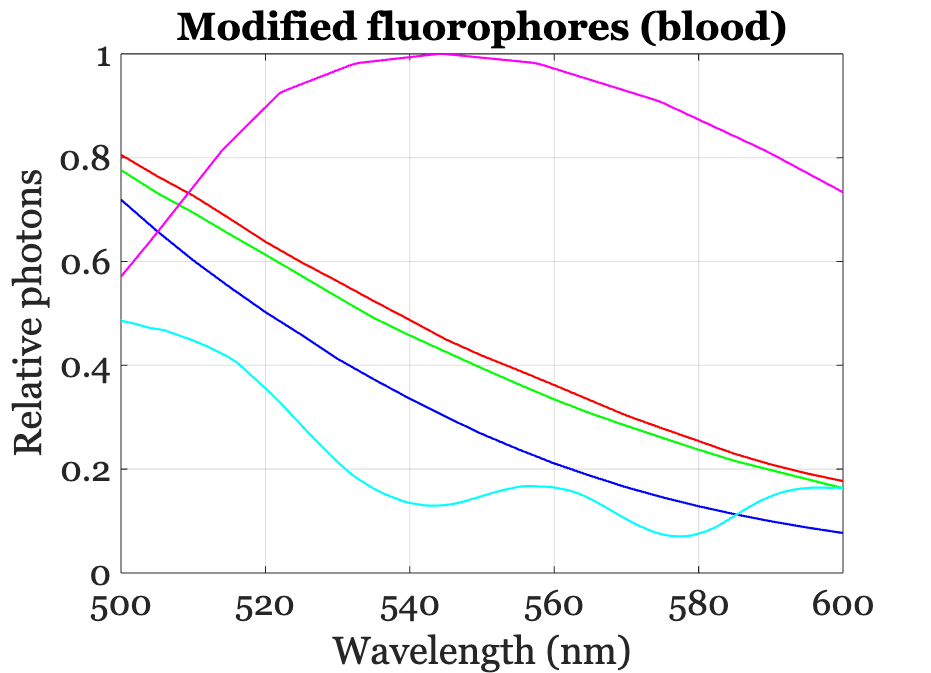


collagenF = fiReadFluorophore('CollagenWuQu');
collagen = fluorophoreGet(collagenF,'normalized emission','wave',wave);

% elastinF = fiReadFluorophore('elastin_webfluor');
% elastin  = fluorophoreGet(elastinF,'normalized emission','wave',wave);

oxyblood.opticalDensity = 5.5;
transmittance = oxyblood.transmittance;
collagenO = collagen(:) .* transmittance(:);
% elastinO = elastin(:) .* transmittance(:);

fluorophoresO = [fluorophores, collagenO(:)];
ieNewGraphWin;
plot(wave,fluorophoresO); title('Modified fluorophores (blood)')
xlabel('Wavelength (nm)'); ylabel('Relative photons'); grid on;

fluorophoreONames = fluorophoreNames;
fluorophoreONames{end+1} = 'CollagenO';
% fluorophoreONames{end+1} = 'ElastinO';

**Tongue: non-negative **

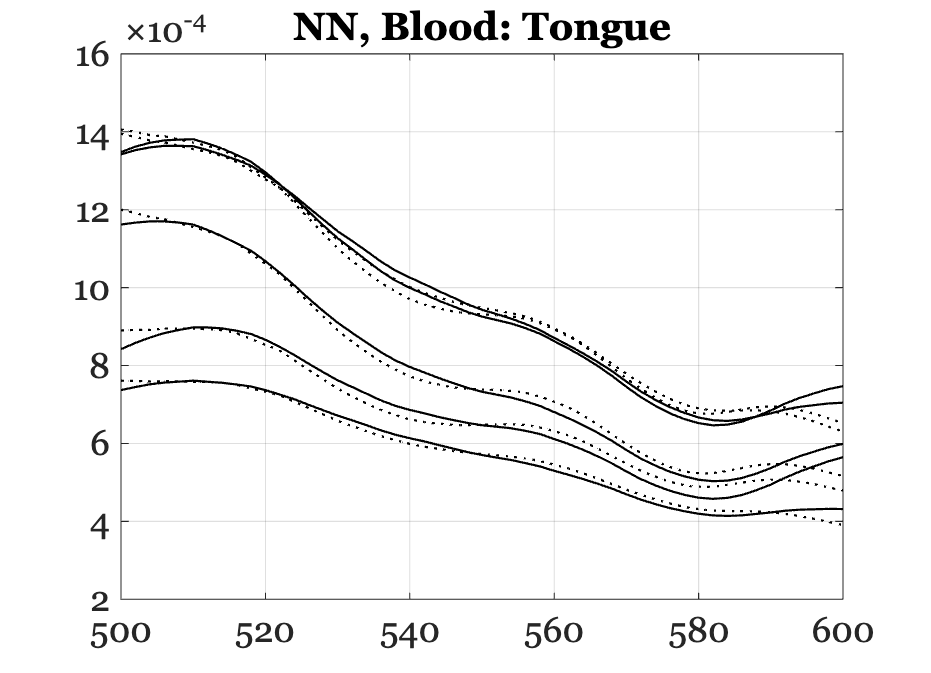

wgtsNN = zeros(size(fluorophoresO,2),size(tongueData,2));

for dd = 1:size(tongueData,2)
    wgtsNN(:,dd) = lsqnonneg(fluorophoresO,tongueData(:,dd));
end

ieNewGraphWin;
plot(wave,tongueData,'k-',wave,fluorophoresO*wgtsNN,'k:');
grid on; title('NN, Blood: Tongue')

disp(fluorophoreONames'); disp(wgtsNN);

    {'CollagenWuQu' }
    {'KeratinWuQu'  }
    {'NADH_webfluor'}
    {'FADLin'       }
    {'CollagenO'    }

         0         0         0         0         0
         0         0         0         0         0
    0.0007    0.0009    0.0005    0.0008    0.0004
    0.0004    0.0006    0.0004    0.0006    0.0004
    0.0010    0.0008    0.0004    0.0011    0.0008



The fits are better, with the biggest miss around 600 nm. Let's look at the weights.  It appears only the 2nd blood modified collagen is used.  It is also using NADH, FAD, and porphyrin.